clearvars -except wire1sorted wire2sorted wire3sorted wire4sorted
lens = 20; %20 40
number_of_wires = 4;
total_time = 0;

if lens == 10
    pixeltoum = 0.65; %um/pixal
elseif lens == 40
    pixeltoum = 0.1625; %um/pixal
end
if number_of_wires == 1
    wire1 = importdata("wire1sorted");
    z_1 = wire1(:,3);
elseif number_of_wires == 2
    wire1 = importdata(wire1sorted);
    wire2 = importdata(wire2sorted);
    z_1 = wire1(:,3);
    z_2 = wire2(:,3);
elseif number_of_wires == 3
    wire1 = importdata(wire1sorted);
    wire2 = importdata(wire2sorted);
    wire3 = importdata(wire3sorted);
    z_1 = wire1(:,3);
    z_2 = wire2(:,3);
    z_3 = wire3(:,3);
elseif number_of_wires == 4
    wire1 = importdata("wire1sorted.txt");
    wire2 = importdata("wire2sorted.txt");
    wire3 = importdata("wire3sorted.txt");
    wire4 = importdata("wire4sorted.txt");
    z_1 = wire1(:,3);
    z_2 = wire2(:,3);
    z_3 = wire3(:,3);
    z_4 = wire4(:,3);
elseif number_of_wires == 5
    wire1 = table2array(wire1sorted);
    wire2 = table2array(wire2sorted);
    wire3 = table2array(wire3sorted);
    wire4 = table2array(wire4sorted);
    wire5 = table2array(wire5sorted);
    z_1 = wire1(:,3);
    z_2 = wire2(:,3);
    z_3 = wire3(:,3);
    z_4 = wire4(:,3);
    z_5 = wire5(:,3);
end

x_axis = zeros(1,length(wire1)+length(wire2)+length(wire3)+length(wire4));
total_time = 0;
for i = 1:length(wire1)
    x_axis (4*i-3) = wire1(i,8);
end
for i = 1:length(wire2)
    x_axis(4*i-2) = wire2(i,8);
end
for i = 1:length(wire3)
    x_axis(4*i-1) = wire3(i,8);
end
for i = 1:length(wire4)
    x_axis(4*i) = wire4(i,8);
end

for i = 1:length(x_axis)
    real_time = x_axis(i);
    total_time = real_time + total_time;
    timeline(i) = total_time;
end
timeline = transpose(timeline);
for i = 1:length(wire1)
    wire1_time(i) = timeline(4*i-3);
end
for i = 1:length(wire2)
    wire2_time(i) = timeline(4*i-2);
end
for i = 1:length(wire3)
    wire3_time(i) = timeline(4*i-1);
end
for i = 1:length(wire4)
    wire4_time(i) = timeline(4*i);
end

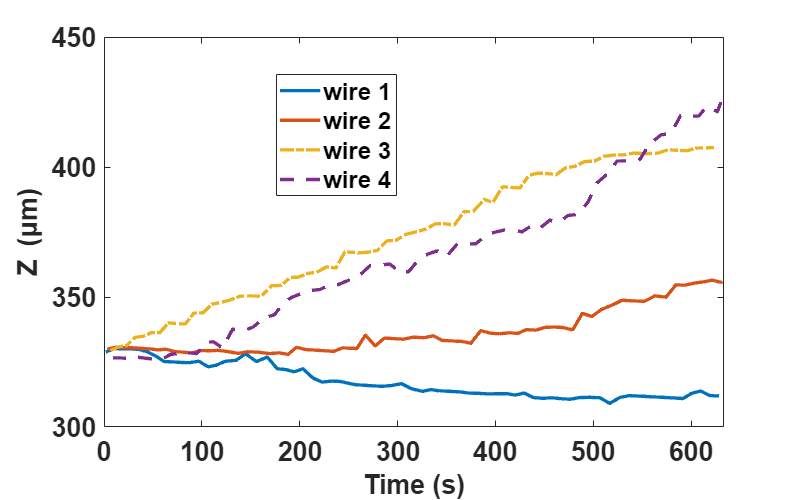

figure(2)
plot(wire1_time, wire1(:,3),'-','LineWidth',2.5); hold on
plot(wire2_time, wire2(:,3),'.-','LineWidth',2.5); hold on
plot(wire3_time, wire3(:,3),'-.','LineWidth',2.5); hold on
plot(wire4_time, wire4(:,3),'--','LineWidth',2.5); hold off
% xlim([0 930])
% ylim([245 340])
ax = gca; 
ax.FontSize = 20; 
ax.FontWeight = 'bold';
xlabel('Time (s)','FontSize',20,'FontWeight','bold');
ylabel('Z (\mum)','FontSize',20,'FontWeight','bold');
legend('wire 1','wire 2','wire 3','wire 4','Location','best','FontWeight','bold')

x0=0; y0=0;
width=800;
height=500;
set(gcf,'position',[x0,y0,width,height])
